In MatLab it is as usual a bit easier. First look at the file

h5disp("data/gammaray_lab4.h5")

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


Then import the data from the data 'directory' withing the hdf5 file

problem1_data = h5read("data/gammaray_lab4.h5",'/data');

and check you got the data imported (python and matlab have different row/column conventions)

problem1_data(1,:)

ans =    940680016         315          45          10


## Problem 1

In this problem we are looking at the data from a gamma-ray satellite  orbiting in low Earth orbit. It takes a reading of the number of  particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.

As with most data, there are 'features.' Your lab instructor has helpfully incorporated the meta-data into your data file.

1)  The columns are time (in gps seconds), Solar  phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the  ground, and particle counts. Make a few plots, generally exploring your  data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see  signal contamination in your data, and how you plan to build a  background pdf().

As the data we care about is counts, to search for contamination in the data, I will be looking at the counts as a function of all the meta data (time, solar phase, and earth longitude).  Note that as these cosmic rays are "rare events" with some rate of number per period of time, we expect that their background pdf with be a Poisson distribution. So we will be looking to figure out the mean of the Poisson distribution to accurately describe our background cosmic rays.

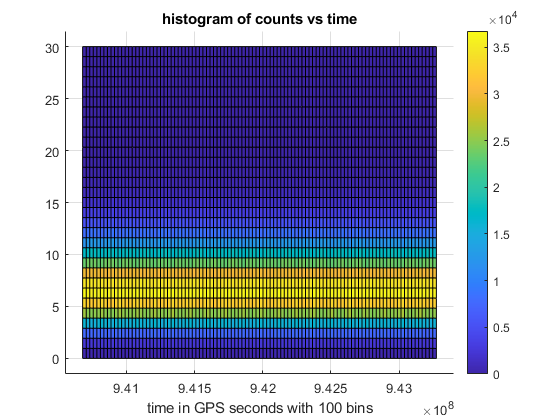


time = problem1_data(:, 1);
solar_phase = problem1_data(:, 2);
earth_long = problem1_data(:, 3);
counts = problem1_data(:, 4);

min_counts = min(counts(:));
max_counts = max(counts(:));

counts_bins = max_counts+1;
solar_phase_bins = 100; % 3.6 degree bins
earth_long_bins = 100; % 3.6 degree bins
time_bins = 100; % nice round number

figure;
hist3([time, counts], 'nbins', [time_bins, counts_bins],'CDataMode','auto', 'FaceColor', 'interp');
colorbar;
title('histogram of counts vs time');
xlabel(['time in GPS seconds with ' num2str(time_bins) ' bins']);
counts(['counts axis with ' num2str(counts_bins) ' bins']);
view(2)

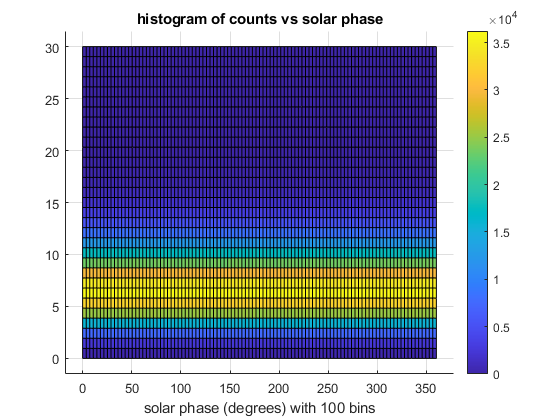

figure;
hist3([solar_phase, counts], 'nbins', [solar_phase_bins, counts_bins],'CDataMode','auto', 'FaceColor', 'interp');
colorbar;
title('histogram of counts vs solar phase');
xlabel(['solar phase (degrees) with ' num2str(solar_phase_bins) ' bins']);
counts(['counts axis with ' num2str(counts_bins) ' bins']);
view(2)

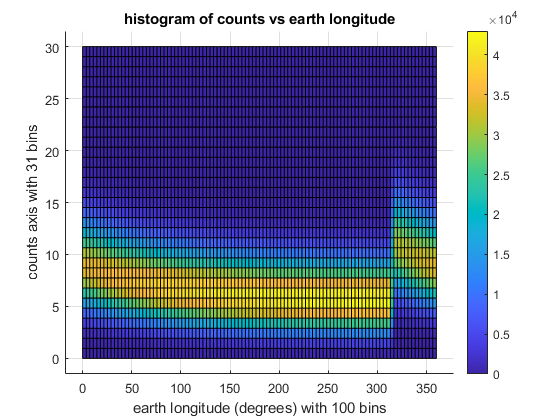


figure;
hist3([earth_long, counts], 'nbins', [earth_long_bins, counts_bins],'CDataMode','auto', 'FaceColor', 'interp');
colorbar;
title('histogram of counts vs earth longitude');
xlabel(['earth longitude (degrees) with ' num2str(earth_long_bins) ' bins']);
ylabel(['counts axis with ' num2str(counts_bins) ' bins']);
view(2)

As shown above, the data clearly shows a dependence on the earth longitude. As the signal we are looking for (cosmic rays from far away objects) should not be impacted by this so uniformly over the time interval (even if the earth was blocking the source of signal, as the earth moves around the sun, this would shift the angle at which the earth blocked our desired signal), it must be the background that is varying. We will construct a background pdf by examining further the apparent dependence of the data on the earth longitude.

2) The background is **not** consistent across the dataset. Find and describe as accurately as you can how the background changes.

To more accurately describe the change in the data, I will first take advantage of the periodicity of earth longitude. To paint a clearer picture, I want to shift the apparent discontinuity to the edge of our domain so it might be easier to fit to the data. To do so, I will more closely examine the data between 310 and 320 degrees of earth longitude, where the disconinuity appears to occur. Recall that we expect our background to be Poisson, and this appears to be so, just with a shifting distribution parameter:

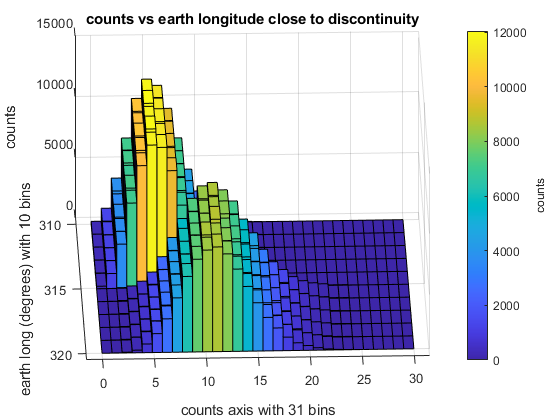

earth_long = problem1_data(:, 3);
counts = problem1_data(:, 4);
lower_bound_angle = 310;
upper_bound_angle = 320;
is_more_than_lb = earth_long > lower_bound_angle;
is_less_than_ub = earth_long < upper_bound_angle;
is_in_range = is_more_than_lb .* is_less_than_ub;
in_range_indices = find(is_in_range);
in_range_counts = counts(in_range_indices);
in_range_angles = earth_long(in_range_indices);

earth_long_bins = (upper_bound_angle - lower_bound_angle);
count_bins = max(in_range_counts) + 1;

figure;
hist3([in_range_angles, in_range_counts], 'nbins', [earth_long_bins, counts_bins],'CDataMode','auto', 'FaceColor', 'flat')
c = colorbar;
c.Label.String = 'counts';
title('counts vs earth longitude close to discontinuity');
ylabel(['counts axis with ' num2str(counts_bins) ' bins']);
xlabel(['earth long (degrees) with ' num2str(earth_long_bins) ' bins']);
zlabel('counts')
view([88 38])

To figure out this discontinuity is, we will group the data in time and fit poisson distributions to the chunked data. Plotting the fit poisson mean as a function of angle:

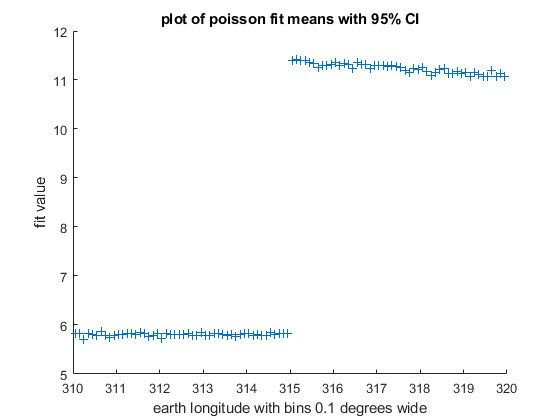

bin_width = 0.1; % degrees
start_angle = 310; %degrees
end_angle = 320;
bin_edges = start_angle:bin_width:end_angle;
bin_centers = bin_edges(1:end-1) + bin_width/2;
fit_values = zeros(1, length(bin_centers));
fit_ci_ub = zeros(1, length(bin_centers));
fit_ci_lb = zeros(1, length(bin_centers));
number_data_points = zeros(1, length(bin_centers));

for i =1:length(bin_centers)
    bin_lower_bound = bin_edges(i);
    bin_upper_bound = bin_edges(i+1);
    indices = find((earth_long > bin_lower_bound).*(earth_long < bin_upper_bound));
    counts_in_range = counts(indices);
    poisson_fit = fitdist(counts_in_range, 'Poisson');
    
    fit_values(i) = poisson_fit.lambda;
    confidence_interval = paramci(poisson_fit);
    fit_ci_ub(i) = confidence_interval(2);
    fit_ci_lb(i) = confidence_interval(1);
    number_data_points(i) = length(counts_in_range);
end

figure

scatter(bin_centers, fit_values, 'Marker', '+')
title('plot of poisson fit means with 95% CI')
xlabel(['earth longitude with bins ' num2str(bin_width) ' degrees wide'])
ylabel('fit value')

It appears that this discontinuity occurs at 315 degrees: 

after_jump = find(fit_values > 9);
disp(['The first bin center whose fit Poisson has a mean greater than 9 is ' num2str(bin_centers(after_jump(1))) ' degrees.'])

The first bin center whose fit Poisson has a mean greater than 9 is 315.05 degrees.


disp(['The bins have a bin width of ' num2str(bin_width) ' degrees.'])

The bins have a bin width of 0.1 degrees.


To make sure that we haven't included some of each side of the discontinuity, we can examine the shape of the 95% confidence interval. If we have a bin that includes some portion on either side of the discontinuity, we would expect the fit to a single poisson distribution to not work very well, increasing the size of 95% confidence interval. Recall that because the mean and variance of a poisson distribution are equal, and we expect the size of the confidence interval to scale with the the square root of the variance and the square root of the number of data points, we will scale them accordingly:

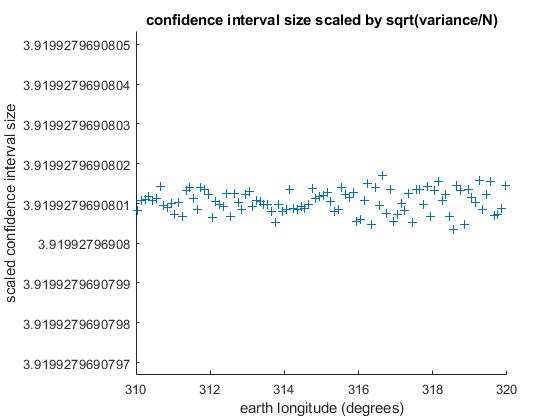


ci_range = fit_ci_ub - fit_ci_lb;
scaled_ci_range = ci_range ./ sqrt(fit_values ./ number_data_points);

figure
scatter(bin_centers, scaled_ci_range, 'Marker', '+')
title('confidence interval size scaled by sqrt(variance/N)')
xlabel('earth longitude (degrees)')
ylabel('scaled confidence interval size')

Because these scaled confidence intervals are roughly uniform over the angle range, we can safely assume that the discontinuity does occur exactly at 315 degrees. Now we can shift the region of angles from [315, 360) to [-45, 0) to get a nicer, continuous plot:

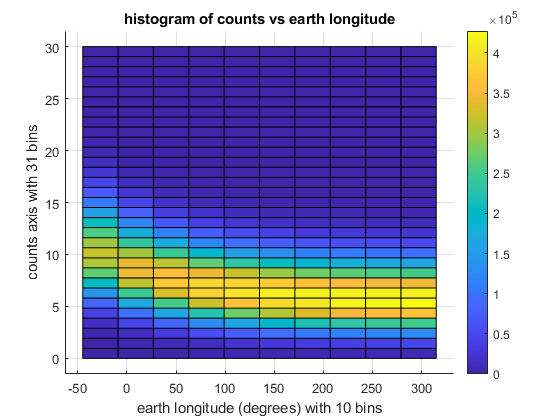

shifted_earth_long = earth_long - 360 *floor(earth_long/315);

figure;
hist3([shifted_earth_long, counts], 'nbins', [earth_long_bins, counts_bins],'CDataMode','auto', 'FaceColor', 'interp');
colorbar;
title('histogram of counts vs earth longitude');
xlabel(['earth longitude (degrees) with ' num2str(earth_long_bins) ' bins']);
ylabel(['counts axis with ' num2str(counts_bins) ' bins']);
view(2)

3) Create a model for the background that includes time dependence,  and explicitly compare your model to the data. How good is your model of the background?

4) Because the background varies, your discovery sensitivity  threshold (how many particles you would need to see) also varies. What  is the '5-sigma' threshold for a 100 millisecond GRB at different times?

Optional:  while this is simulated data, it is based on a real effect seen by low Earth orbit satellites. Can you identify the cause of the variable background and propose a physical model?

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be  looking for different signals. One of you will be looking for the  faintest stars, while the other will be looking for a transient  (something like a super novae that only appears in one image). Flip a  coin to determine which of you is pursuing which question.

1) Dowload the data from `images.h5`. This is a stack of 10 square images, each 200 pixels on a side.

h5disp("data/images.h5")

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


problem2_data = h5read("data/images.h5",'/imagestack');

2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().

First let us examine the first frame of the image stack.

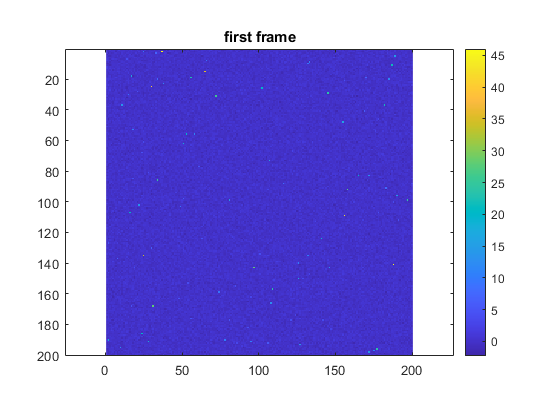

first_frame = squeeze(problem2_data(1, :, :));

figure
imagesc(first_frame)
axis equal
colorbar
title('first frame')

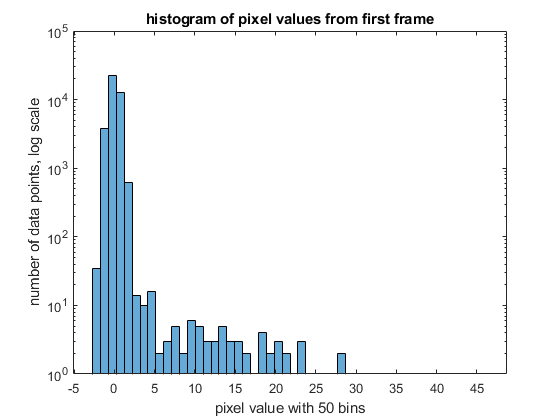

nbins = 50;
figure
histogram(first_frame(:), 'NumBins', nbins)
title('histogram of pixel values from first frame')
xlabel(['pixel value with ' num2str(nbins) ' bins'])
ylabel('number of data points, log scale')
set(gca, 'Yscale', 'log')

We can see that there are several bright punctua along a mostly flat background. The majority of the data points seem to be clustered around a signal of zero. This matches my anticipated structure of the data. Assuming these images were taken on a ccd camera, similar to previous "telescope images" used in this class, we anticipate that background will be a mean zero gaussian with some as-yet unknown standard deviation. In fact, throwing out the top 50 or so values (the extremely bright stars we can even see by eye), we see this to be a good initial guess:

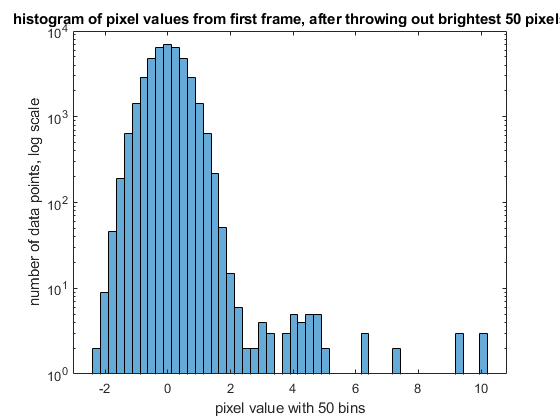

sorted_first_frame_vals = sort(first_frame(:));
data_points_to_throw_out = 50;
pruned_first_frame_data = sorted_first_frame_vals(1:end-data_points_to_throw_out);
nbins = 50;
figure
histogram(pruned_first_frame_data(:), 'NumBins', nbins)
title(['histogram of pixel values from first frame, after throwing out brightest ' num2str(data_points_to_throw_out) ' pixels'])
xlabel(['pixel value with ' num2str(nbins) ' bins'])
ylabel('number of data points, log scale')
set(gca, 'Yscale', 'log')

This hasn't eliminated all of the non-Gaussian signal, but 50 was just a rough estimate of the number of stars visibile in the first frame to the naked eye. Because signal is more positive, one stands to reason that all of the negative values are coming from the background distribution for each pixel. Note that it is still possible there is actual signal hidden in a negative value, but that means the signal for this image is smaller than the negative background fluctuation. But, continuing to assume this mean zero background distribution for pixels where this is no signal seems valid. Additionally, I am tentatively hopeful that the background distribution doesn't have significant spatial variation. As of yet, no purported fit has been proposed, but the bulk of the data (which we assume will be background) seems to fit under a single gaussian (this will be further tested later). If there was significant variation in the background spatially, we would expect a histogram of the entire image to be well fit by a single gaussian (modulo signal). The issue is, we have all these points with signal, and can't throw them out (especially because we don't know what they are). So, now we will look at consecutive difference images for the data to see if the distribution shifts as a function of time. The idea is that this shows the variation for a single pixel from one frame to the next, so we can include the data points for fixed stars as we now only see the fluctuation on top of the signal. Notably, transients will cause issues with this. Because a transient signal is there for only a single frame, taking consecutive differences will not be just the fluctuations for that pixel. The same is true if the star brightness was changing appreciably between frames, or over the course of the entire data taking. Because we expect the number of transients to be small, I have chosen not to attempt to prune their pixels from the data and anticipate their presence will not overly adjust the fit parameters. 

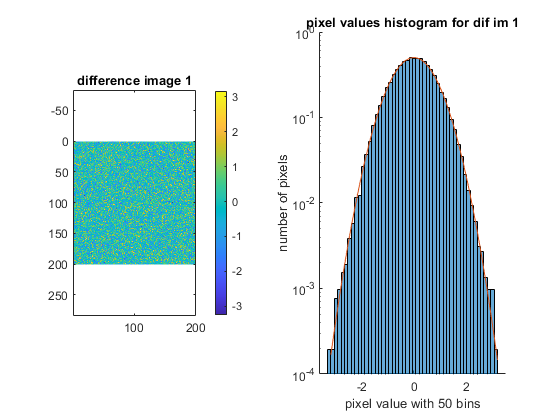

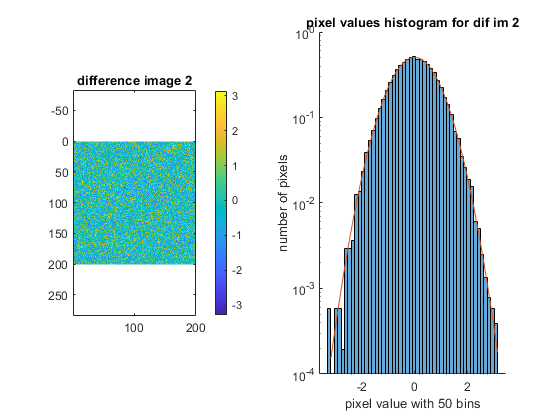

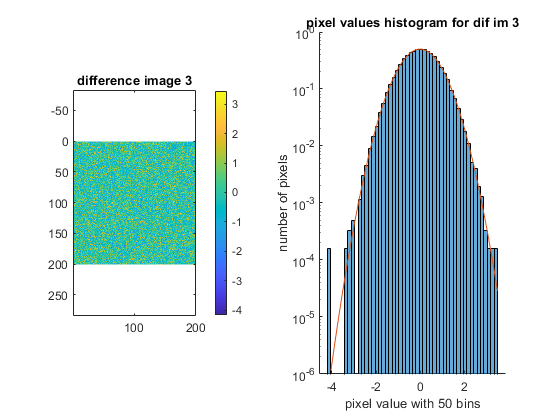

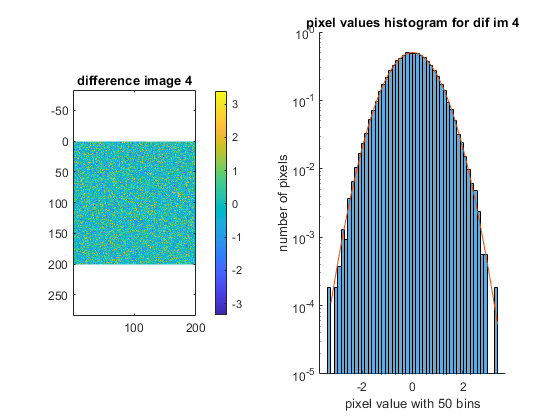

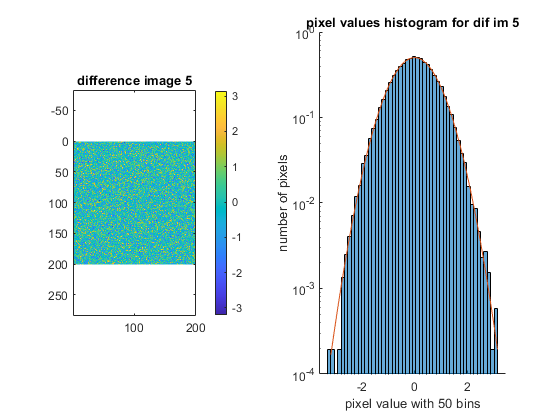

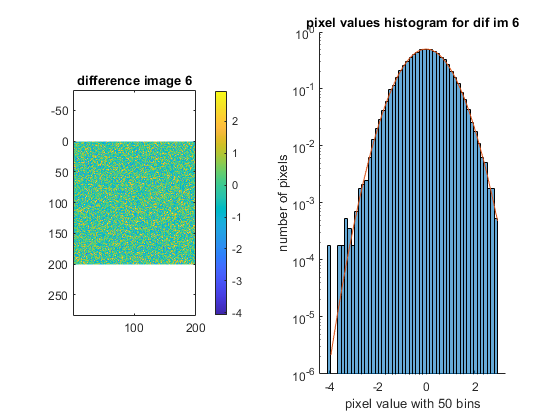

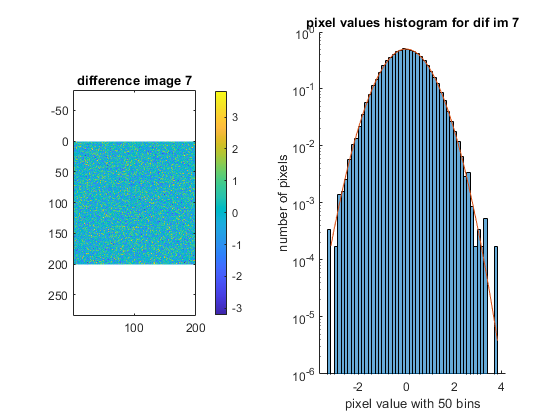

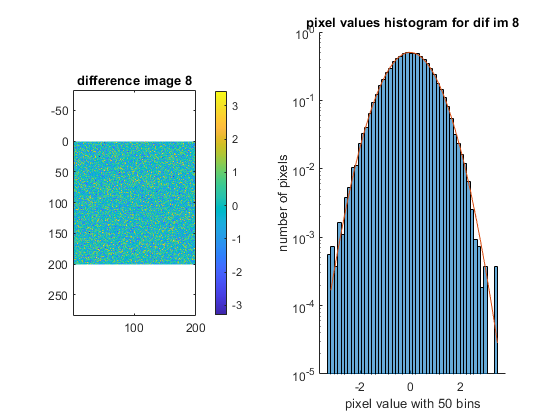

size_problem2_data = size(problem2_data);

difference_images = zeros(size_problem2_data(1)-1, size_problem2_data(2), size_problem2_data(3));

last_dif_image = size_problem2_data(1)-1; 

fit_gaussian_means = zeros(1,last_dif_image);
fit_gaussian_stds = zeros(1,last_dif_image);
mean_lower_bound = zeros(1,last_dif_image);
mean_upper_bound = zeros(1,last_dif_image);
std_lower_bound = zeros(1,last_dif_image);
std_upper_bound = zeros(1,last_dif_image);

for i=1:last_dif_image
    
    difference_image_frame = squeeze(problem2_data(i+1, :, :) - problem2_data(i, :, :));
    
    difference_images(i, :, :) = difference_image_frame;
    
    hist_data = difference_image_frame(:);
    
    % plot the difference image
    figure
    subplot(1,2,1)
    imagesc(difference_image_frame)
    title(['difference image ' num2str(i)])
    axis equal
    colorbar
    
    % plot a histogram of pixels in difference image
    subplot(1,2,2)
    nbins = 50;
    hold on
    difference_hist = histogram(hist_data, 'NumBins', nbins, 'Normalization','pdf');
    
    % fit a gaussian to the data and plot over histogram 
    fit_gaussian = fitdist(hist_data, 'Normal');
    confidence_intervals = paramci(fit_gaussian);
    bin_centers = difference_hist.BinEdges(1:end-1) + difference_hist.BinWidth;
    gaussian_to_plot = pdf(fit_gaussian, bin_centers);
    plot(bin_centers, gaussian_to_plot)
    hold off
    
    % titles and set y-axis to log
    title(['pixel values histogram for dif im ' num2str(i)])
    xlabel(['pixel value with ' num2str(nbins) ' bins'])
    ylabel(['number of pixels'])
    set(gca, 'Yscale', 'log')
    pause(0.1)
    
    % pass histogram data, fit parameters and confidence intervals out
    fit_gaussian_means(i) = fit_gaussian.mu;
    fit_gaussian_stds(i) = fit_gaussian.sigma;
    mean_lower_bound(i) = confidence_intervals(1);
    mean_upper_bound(i) = confidence_intervals(2);
    std_lower_bound(i) = confidence_intervals(3);
    std_upper_bound(i) = confidence_intervals(4);
    
end

Each of the 9 difference images seems to be well fit by a single gaussian (further seen by how narrow the confidence intervals are below). This seems to further support the idea that there is not significant spatial variation in the background for these images. As mentioned earlier, we would expect a single gaussian to be a bad fit for the data over the entire image if there was spatial fluctuation in the background. There are several strange outliers that seem to buck the gaussian fit, but I feel confident in labeling them as transients. Their removal would not significantly adjust the gaussian fit though, so I will again leave them in.

Now we plot the fit parameters and their confidence intervals for the fit gaussians above to examine variation in the background as a function of time:

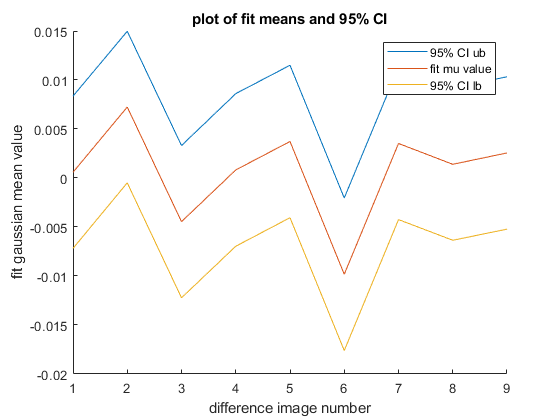


    figure
    hold on
    plot(mean_upper_bound)
    plot(fit_gaussian_means)
    plot(mean_lower_bound)
    hold off
    title('plot of fit means and 95% CI')
    xlabel('difference image number')
    ylabel('fit gaussian mean value')
    legend({'95% CI ub', 'fit mu value', '95% CI lb'})

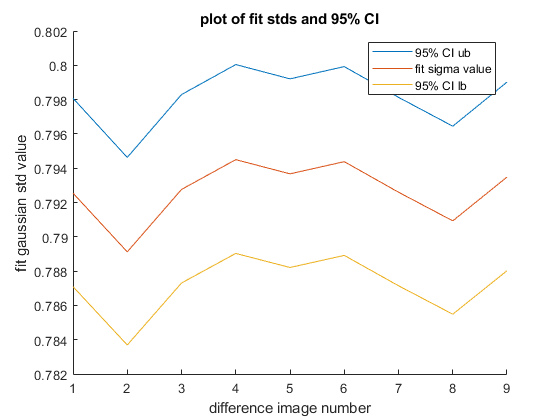

    pause(0.1)
    
    figure
    hold on
    plot(std_upper_bound)
    plot(fit_gaussian_stds)
    plot(std_lower_bound)
    hold off
    title('plot of fit stds and 95% CI')
    xlabel('difference image number')
    ylabel('fit gaussian std value')
    legend({'95% CI ub', 'fit sigma value', '95% CI lb'})

    pause(0.1)

While the fit values for the standard deviations appears very flat over all the difference images, the fit mean appears to undergo more variation. Specifically, while most of the fit means seems to nicely saddle the expected mean of 0 (if we anticipate no temporal change in the background pdf) difference image 2 the mean seems a little high and difference image 6 the mean seems a little low. However, compared to the standard deviation values, these fluctuations are extremely small, with the variation between extremes for the means being on the order of 2 percent of a single standard deviation:

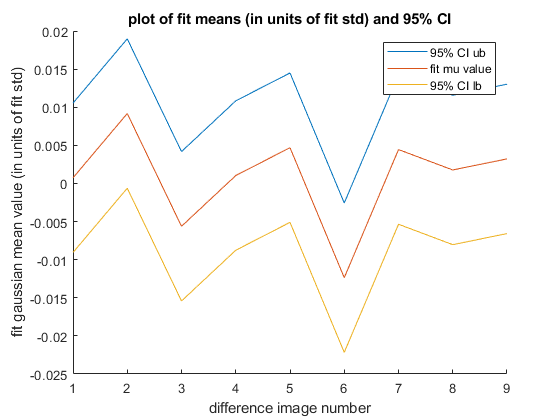

    figure
    hold on
    plot(mean_upper_bound./fit_gaussian_stds)
    plot(fit_gaussian_means./fit_gaussian_stds)
    plot(mean_lower_bound./fit_gaussian_stds)
    hold off
    title('plot of fit means (in units of fit std) and 95% CI')
    xlabel('difference image number')
    ylabel('fit gaussian mean value (in units of fit std)')
    legend({'95% CI ub', 'fit mu value', '95% CI lb'})

    pause(0.1)

I will consider this variation small enough that there is no temporal variation in the background. This allows us to fit to the background of all 9 difference images simultaneously. Again some of the more extreme values may be transients, but removing them will not significantly adjust the fit values.

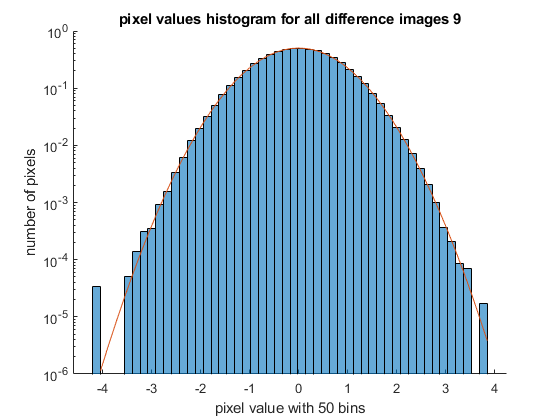

    raw_data = difference_images(:);
    
    sorted_data = sort(raw_data);
    
    prune_number = 0;
    
    pruned_data = sorted_data(1+prune_number:end-prune_number);
    
    hist_data = pruned_data;
    
    figure
    
    % plot a histogram of pixels in difference image
    nbins = 50;
    hold on
    difference_hist = histogram(hist_data, 'NumBins', nbins, 'Normalization','pdf');
    
    % fit a gaussian to the data and plot over histogram
    fit_gaussian = fitdist(hist_data, 'Normal');
    confidence_intervals = paramci(fit_gaussian);
    bin_centers = difference_hist.BinEdges(1:end-1) + difference_hist.BinWidth;
    gaussian_to_plot = pdf(fit_gaussian, bin_centers);
    plot(bin_centers, gaussian_to_plot)
    hold off
    
    % titles and set y-axis to log
    title(['pixel values histogram for all difference images ' num2str(i)])
    xlabel(['pixel value with ' num2str(nbins) ' bins'])
    ylabel(['number of pixels'])
    set(gca, 'Yscale', 'log')

    pause(0.1)
    fit_gaussian

fit_gaussian =   NormalDistribution

  Normal distribution
       mu = 0.000620359   [-0.001969, 0.00320972]
    sigma =    0.792673   [0.790847, 0.794509]


Recall that this is a difference image distribution. The actual background pdf that I need is for the average of all 10 images. Using our results from homework 2, we know that if we take the average of $N$ identical gaussian distributions, the mean remains the same while the standard deviation shrinks by a factor of $\sqrt{N}$. Reducing our background's standard deviation will make it easier to identify signal, which we have identified as more positive pixel values. Because I am working with the (justified) assumption that the background does not vary spatially or temporally, I am looking for the single pixel background distribution for a averaging 10 of these images together. Because I am assuming for the vast majority of the pixels that variation from image to image only comes from the background, it is safe to say that the standard deviation of the background for a single pixel in a single image will be that of the difference image fit divided by $\sqrt{2}$. This comes from the fact taking the difference of the two gaussian distributions, we know the variances will add. And because we are assuming that the background distribution is not a function of time, we expect a single pixel for a single image to have a background with variance equal to half of the difference image variance. This leads me to the final background distribution: a gaussian distribution with standard deviation listed below:

background_std_single_frame = fit_gaussian.sigma/sqrt(2)

background_std_single_frame = 0.5605

background_std_for_averaging_frames = background_std_single_frame/sqrt(10)

background_std_for_averaging_frames = 0.1772

Now for the mean of this gaussian background distribution. We cannot simply grab the difference image mean, as even if the background had a non-zero mean, the difference images would have zero mean. Instead, as I suspect the mean of the background should be around zero, we will fit a gaussian to all of pixels values within 4 standard deviations of 0. Note that we didn't just start by doing this, because we didn't know where to put the cut off! Looking at the difference image distribution allowed us to obtain the standard deviation for the background that we will be using. Below we simply provide an argument for assuming a background of 0:

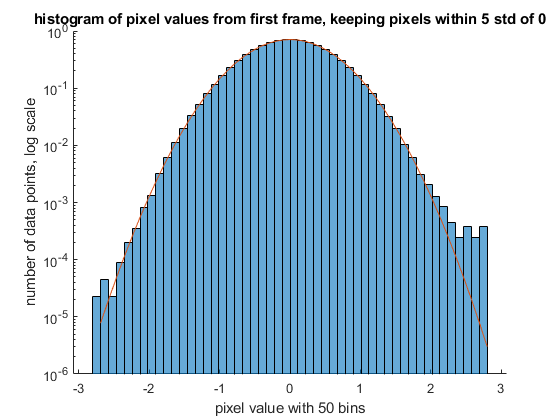

raw_data = first_frame(:);
raw_data = problem2_data(:);
z_value = raw_data / background_std_single_frame;
n_sigma = 5;
inside_n_sigma = abs(z_value) < n_sigma;
include_indices = find(inside_n_sigma);
selected_data = raw_data(include_indices);


nbins = 50;
figure
hold on 
hist = histogram(selected_data, 'NumBins', nbins, 'Normalization','pdf');

fit_gaussian = fitdist(selected_data, 'Normal');
bin_centers = hist.BinEdges(1:end-1) + hist.BinWidth;
gaussian_to_plot = pdf(fit_gaussian, bin_centers);
plot(bin_centers, gaussian_to_plot)
hold off

title(['histogram of pixel values from first frame, keeping pixels within ' num2str(n_sigma) ' std of 0'])
xlabel(['pixel value with ' num2str(nbins) ' bins'])
ylabel('number of data points, log scale')
set(gca, 'Yscale', 'log')

fit_gaussian

fit_gaussian =   NormalDistribution

  Normal distribution
       mu = 0.000972846   [-0.000773021, 0.00271871]
    sigma =    0.562666   [0.561434, 0.563903]


As we can see, this standard deviation of this matches very closely with the standard deviation predicted by difference image fit! Also, the mean is ~(1/500) of a standard deviation away from zero. Given that the means for the difference image were comparably small in those units it suggests that the mean for this gaussian background bump is 0 (matching our initial understanding of the problem). 

3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.

Recall that we are looking for signal in the average of all 10 images. Our assumed background distribution is a gaussian with mean 0 and standard deviation of:

background_std_for_averaging_frames

background_std_for_averaging_frames = 0.1772

for each pixel. I will now locate all pixels that have a 5 sigma detection tolerance, applying a penalty for the 40000 trials (pixels). That is to say I will identify a pixel as being a star if the probability of it being as bright as it is due to just the expected background on a single pixel is less than or equal to the probability of a value pulled from a normal distribution with mean 0 and standard deviation of 1 being greater than or equal to 5. With an additional penalty to this probability due to the fact that I am looking at 40000 pixels looking for these stars. 

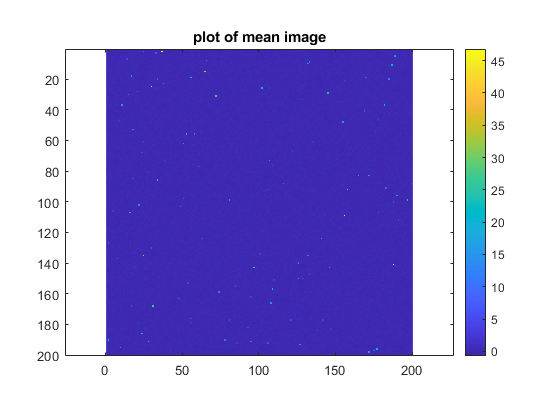

mean_image = squeeze( sum(problem2_data, 1) / size_problem2_data(1) );

figure
imagesc(mean_image)
title('plot of mean image')
axis equal
colorbar


five_sigma_prob = 1 - normcdf(5);
trials_factor = size_problem2_data(2)*size_problem2_data(3);
trials_factor_five_sigma_prob = five_sigma_prob / trials_factor;
five_sigma_cutoff = norminv(1-trials_factor_five_sigma_prob, 0, background_std_for_averaging_frames);
five_sigma_signal = mean_image > five_sigma_cutoff;
five_sigma_pixels = find(five_sigma_signal);
number_of_five_sigma_pixels = length(five_sigma_pixels)

number_of_five_sigma_pixels = 122

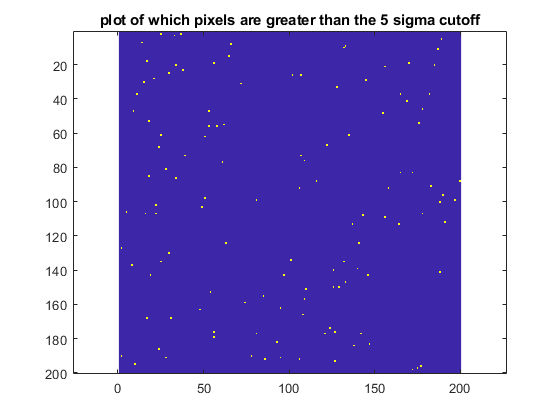


figure
imagesc(five_sigma_signal)
title('plot of which pixels are greater than the 5 sigma cutoff')
axis equal

So here it is. First, we should that the background for each pixel is roughly constant in space and time, then we construct a background pdf for a single pixel with no signal, then we use that to generate the background pdf for a single pixel that is the average of 10 pixels (along the time axis), then we apply a trials factor for the number of pixels in the mean image, and the result is the 122 yellow pixels above. These are the pixels identified as having stationary stars at their location. We can look at a histogram of their values:

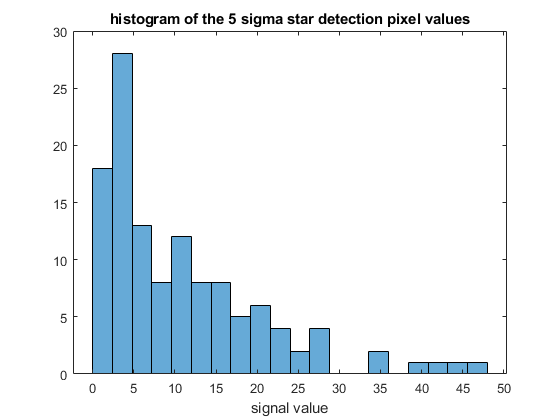

stars = mean_image(five_sigma_pixels);

figure
nbins = 20;
histogram(stars, nbins)
title('histogram of the 5 sigma star detection pixel values')
xlabel('signal value')

And we can look at all of the data points that our test doesn't count as stars to re-verify our background:

non_five_sigma_pixels = find(~five_sigma_signal);
background = mean_image(non_five_sigma_pixels);
background_fit = fitdist(background, 'Normal')

background_fit =   NormalDistribution

  Normal distribution
       mu = -7.42492e-05   [-0.00182136, 0.00167287]
    sigma =     0.178003   [0.176776, 0.179247]


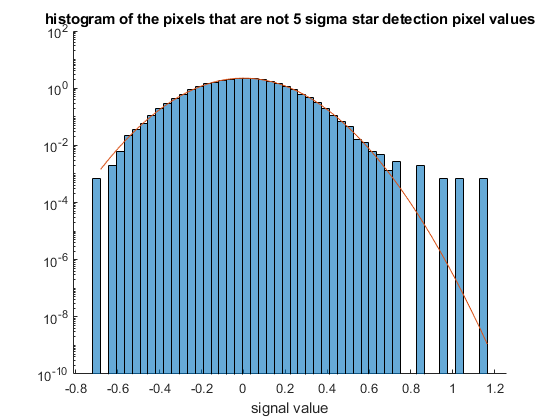


figure
nbins = 50;
hold on
h = histogram(background, nbins, 'Normalization','pdf');

bin_centers = h.BinEdges(1:end-1)+h.BinWidth;
fit_pdf = pdf(background_fit, bin_centers);
plot(bin_centers, fit_pdf)

hold off
title('histogram of the pixels that are not 5 sigma star detection pixel values')
xlabel('signal value')
set(gca, 'Yscale', 'log')

Clearly there are still some points here that may not belong in the background, but don't quite meet the 5 sigma detection threshhold. But for the most part, the fit works very well. 

Interestingly, even if we allow for a slightly non-zero mean for the background as may have been suggested, doesn't change which pixels are identified. 

five_sigma_prob = 1 - normcdf(5);
trials_factor = size_problem2_data(2)*size_problem2_data(3);
trials_factor_five_sigma_prob = five_sigma_prob / trials_factor;
% the "slight" non zero value for the mean is the upper bound of the 95% CI
% for the mean fit for the restricted region of data
five_sigma_cutoff = norminv(1-trials_factor_five_sigma_prob, 0.0027, background_std_for_averaging_frames);
five_sigma_signal_new = mean_image > five_sigma_cutoff;
five_sigma_pixels = find(five_sigma_signal_new);
number_of_five_sigma_pixels = length(five_sigma_pixels)

number_of_five_sigma_pixels = 122

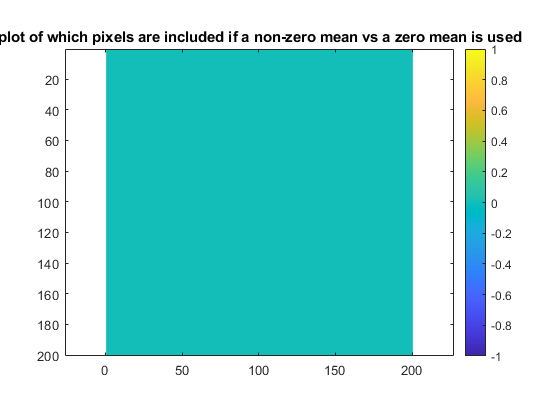


figure
imagesc(five_sigma_signal_new .* (~five_sigma_signal) - (~five_sigma_signal_new) .* five_sigma_signal)
title('plot of which pixels are included if a non-zero mean vs a zero mean is used')
axis equal
colorbar

This very boring plot shows that even if you allow for a slightly positive mean, it does not change which pixels are identified as stars. Below we show the same for a slightly negative mean:

five_sigma_prob = 1 - normcdf(5);
trials_factor = size_problem2_data(2)*size_problem2_data(3);
trials_factor_five_sigma_prob = five_sigma_prob / trials_factor;
% the "slight" non zero value for the mean is the lower bound of the 95% CI
% for the mean fit for the restricted region of data
five_sigma_cutoff = norminv(1-trials_factor_five_sigma_prob, -0.008, background_std_for_averaging_frames);
five_sigma_signal_new = mean_image > five_sigma_cutoff;
five_sigma_pixels = find(five_sigma_signal_new);
number_of_five_sigma_pixels = length(five_sigma_pixels)

number_of_five_sigma_pixels = 122

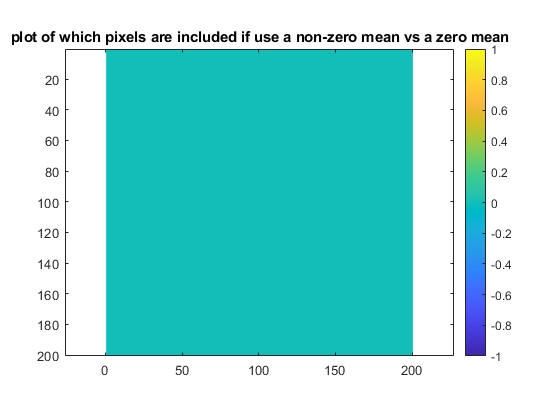


figure
imagesc(five_sigma_signal_new .* (~five_sigma_signal) - (~five_sigma_signal_new) .* five_sigma_signal)
title('plot of which pixels are included if use a non-zero mean vs a zero mean')
axis equal
colorbar

4) You and your lab partner had different pdf(), but were using the *same* data. Explore why this is.

The background pdf that you are comparing to is for your signal, not just for the data. On the way to calculating the background pdf for my signal, I created a background pdf an each individual pixel in a single image. This distribution should be the same for both my partner and I. But when you are attempting to find a signal, you compare to the background pdf of the signal, not the background pdf of a single piece of data that was collected! Consider a smaller example. My friend and I measure the temperature on two days. We use the same thermometer both days that we know the precision of. If I am curious about comparing the average temperature of those two days to the average from previous years and my friend is interested in comparing the change in temperature between the two days, even though we have very simple data (two points!) and we are using the same data, it would make no sense at all to use the same pdf to describe the range of values we expect. The signals people look for are often combinations of a variety of measurements. Thus, the background for a single one of those measurements is not sufficient to describe the background of the signal. And so one must be careful to combine the background pdfs for individual measurements to accurately predict what the background distribution is for the desired signal. 